# Detect Objects Using YOLOv8 Network Deployed To FPGA

This example shows how to deploy a trained You Only Look Once (YOLO) v8 object detector to a target FPGA board.

## Download the Pretrained Network

Load the network. This example uses `Yolov8n`, the nano version of the YOLOv8 pretrained model.

% Add the YOLOv8 files onto the MATLAB path
addpath(genpath("Pretrained-YOLOv8-Network-For-Object-Detection-main"));
% Load the network
modelName = 'yolov8n';
model = helper.downloadPretrainedYOLOv8(modelName);

Pretrained yolov8n network already exists.



net = model.yolov8Net

net =   dlnetwork with properties:

         Layers: [213×1 nnet.cnn.layer.Layer]
    Connections: [303×2 table]
     Learnables: [126×3 table]
          State: [0×3 table]
     InputNames: {'images'}
    OutputNames: {'x_model_22_Concat'  'x_model_22_Concat_1'  'x_model_22_Concat_2'}
    Initialized: 1

  View summary with summary.


Preprocess the network to be compatible for deployment.

net = helper.hdl.preprocessNetwork(net);

### Replacing split layer 'splitLayer1' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer2' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer3' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer4' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer5' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer6' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer7' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer8' with a dlhdl.layer.sliceLayer.
### Replacing sigmoid and multiplication layers 'x_model_0_act_Sigm_1' and 'x_model_0_act_Mul' with a swishLayer having the name 'x_model_0_act_Mul'.
### Replacing sigmoid and multiplication layers 'x_model_1_act_Sigm_1' and 'x_model_1_act_Mul' with a swishLayer having the name 'x_model_1_act_Mul'.
### Replacing sigmoid and multiplication layers 'x_model_2_cv1_act__2' and 'x_model_2_cv1_act__1' with a swishLayer having the name 

Load the test image and perform a detection on it.

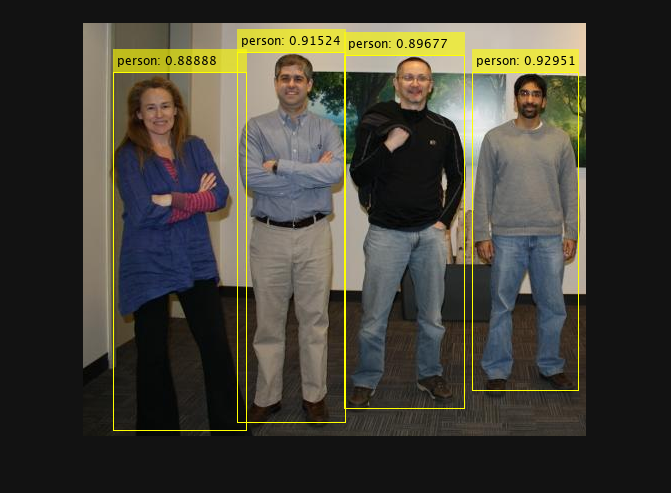

% Read test image.
img = imread(fullfile('data','inputTeam.jpg'));

% Get number of output classes of the network
classNames = helper.getCOCOClassNames;
numClasses = size(classNames,1);
% Perform detection
executionEnvironment = 'auto';
[bboxes,scores,labelIds] = detectYOLOv8(net, img, numClasses, executionEnvironment);

% Map labelIds back to labels.
labels = classNames(labelIds);

% Visualize detection results.
annotations = string(labels) + ': ' + string(scores);
Iout = insertObjectAnnotation(img, 'rectangle', bboxes, annotations);
figure, imshow(Iout)

## Configure Deep Learning Processor and Generate a Bitstream

The network includes several swish layers. To deploy the network to the FPGA hardware, you must turn on the `SwishLayer` property of the `custom` module in the deep learning processor configuration. 

You can create a `dlhdl.ProcessorConfig` object from an existing bitstream and then modify the processor configuration properties to generate a custom bitstream. In this example, the target FPGA board is the Xilinx Zynq® UltraScale+™ MPSoC ZCU102 board and the date type is int8. `hPC` stores the deep learning processor configuration object created from the `zcu102_int8` bitstream. Enable the `SwishLayer` property of the `custom` module, and turn off the `SegmentationBlockGeneration` property to save FPGA resources.  

To learn how to use the generated bitstream file, see [Generate Custom Bitstream](docid:dlhdl_ug#mw_271be8bd-b787-43d3-a753-bc943d255d48).

## Deploy Quantized Network to FPGA

Preprocess the input data set to prepare the images for `int8` data type quantization.

imPre = helper.hdl.preprocessYOLOv8Input(net, img);

Quantize the network by using the `dlquantizer` object. Use the `calibrate` method to exercise the network by using sample inputs to collect the range information.

dlQuantObj = dlquantizer(net,'ExecutionEnvironment','FPGA');
dlQuantObj.calibrate(imPre);
qnet = dlQuantObj.quantize;

Define the target FPGA board programming interface by using the `dlhdl.Target` object. Specify that the interface is for a Xilinx board with an Ethernet interface.

hTarget = dlhdl.Target('Xilinx', 'Interface', 'Ethernet');

Prepare the network for deployment by creating a `dlhdl.Workflow` object. Specify the quantized network and the bitstream name. In this example, the target FPGA board is the Xilinx Zynq® UltraScale+™ MPSoC ZCU102 board. The bitstream uses the `int8` data type. Use the bitstream generated earlier.

bitstreamPath = fullfile('dlhdl_prj','dlprocessor.bit');
hW = dlhdl.Workflow("Network", qnet, "Bitstream", bitstreamPath, "Target", hTarget);

To compile the network and generate the instructions, weights, and biases for deployment, run the `compile` method of the `dlhdl.Workflow` object.

dn = compile(hW)

### Compiling network for Deep Learning FPGA prototyping ...
### Targeting FPGA bitstream Z:\32\vikramv.BR2025bd.j3130065.yolov8\user\Pretrained-YOLOv8-Network-For-Object-Detection-main\Pretrained-YOLOv8-Network-For-Object-Detection-main\dlprocessor.bit.
### An output layer called 'Output1_x_model_22_Concat' of type 'nnet.cnn.layer.RegressionOutputLayer' has been added to the provided network. This layer performs no operation during prediction and thus does not affect the output of the network.
### An output layer called 'Output2_x_model_22_Concat_1' of type 'nnet.cnn.layer.RegressionOutputLayer' has been added to the provided network. This layer performs no operation during prediction and thus does not affect the output of the network.
### An output layer called 'Output3_x_model_22_Concat_2' of type 'nnet.cnn.layer.RegressionOutputLayer' has been added to the provided network. This layer performs no operation during prediction and thus does not affect the output of the network.
### Th

dn = struct with fields:
             weights: [1×1 struct]
        instructions: [1×1 struct]
           registers: [1×1 struct]
    syncInstructions: [1×1 struct]
        constantData: {}
             ddrInfo: [1×1 struct]
       resourceTable: [6×2 table]


To deploy the network on the Xilinx ZCU102 SoC hardware, run the `deploy` method of the `dlhdl.Workflow` object. This function uses the output of the `compile` function to program the FPGA board and download the network weights and biases. The `deploy` function starts programming the FPGA device and displays progress messages, and the required time to deploy the network.

hW.deploy

### Programming FPGA Bitstream using Ethernet...
### Attempting to connect to the hardware board at 192.168.1.101...
### Connection successful
### Programming FPGA device on Xilinx SoC hardware board at 192.168.1.101...
### Attempting to connect to the hardware board at 192.168.1.101...
### Connection successful
### Copying FPGA programming files to SD card...
### Setting FPGA bitstream and devicetree for boot...
# Copying Bitstream dlprocessor.bit to /mnt/hdlcoder_rd
# Set Bitstream to hdlcoder_rd/dlprocessor.bit
# Copying Devicetree devicetree_dlhdl.dtb to /mnt/hdlcoder_rd
# Set Devicetree to hdlcoder_rd/devicetree_dlhdl.dtb
# Set up boot for Reference Design: 'AXI-Stream DDR Memory Access : 3-AXIM'
### Programming done. The system will now reboot for persistent changes to take effect.
### Rebooting Xilinx SoC at 192.168.1.101...
### Reboot may take several seconds...
### Attempting to connect to the hardware board at 192.168.1.101...
### Connection successful
### Programming the FPG

Get the activations of the network using the `predict` method of the `dlhdl.Workflow` object.

hwprediction = cell(length(net.OutputNames), 1);
[hwprediction{:}] = hW.predict(dlarray(imPre,'SSCB'), 'Profile', 'on');

### Finished writing input activations.
### Running single input activation.


              Deep Learning Processor Profiler Performance Results

                   LastFrameLatency(cycles)   LastFrameLatency(seconds)       FramesNum      Total Latency     Frames/s
                         -------------             -------------              ---------        ---------       ---------
Network                   34274579                  0.13710                       1           33079036              7.6
    x_model_0_conv_Conv     972315                  0.00389 
    x_model_0_act_Mul       488653                  0.00195 
    x_model_1_conv_Conv     597276                  0.00239 
    x_model_1_act_Mul       244829                  0.00098 
    x_model_2_cv1_conv_1    703294                  0.00281 
    x_model_2_cv1_act__1    244785

Process the FPGA output using the `postprocessYOLOv8Output` function.

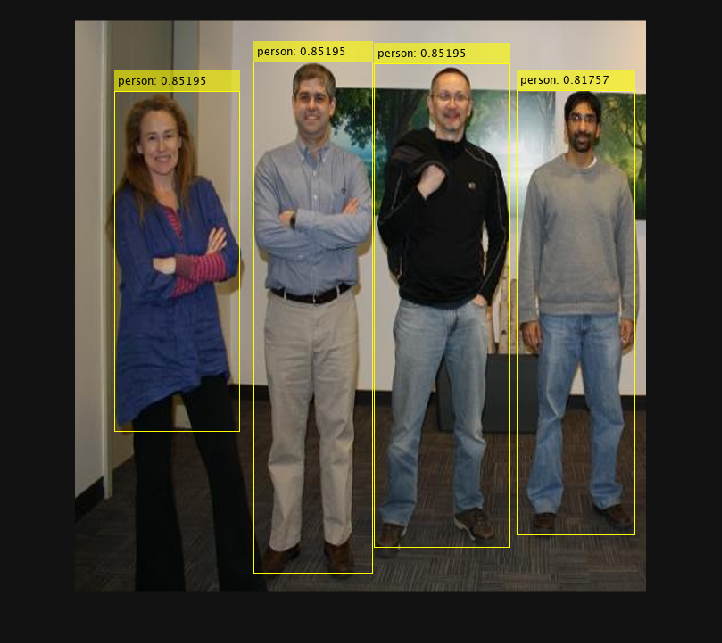

[bboxes,scores,labels] = helper.hdl.postprocessYOLOv8Output(hwprediction, imPre, numClasses, classNames);

% Visualize detection results.
annotations = string(labels) + ': ' + string(scores);
Iout = insertObjectAnnotation(imresize(img,[640,640]), 'rectangle', bboxes, annotations);
figure, imshow(Iout);

*Copyright 2025-2026 The MathWorks, Inc.*